# Flexibility/Mechanics test - Group data Analysis

Developed by Pedro Valadão (pvaladao@tuta.io). Last Modified: 16/04/2021.

*Sample: 15 CP + 15 TD + 1 SDR case study (5105). 1 TD (5202) has only ankle joint flexibility test (only usable var). 1 CP has no good mechanical data due to emg and heel sensor problem (5102).*

*Notes: 1) 12 deg was subtracted from max ROM and passive ROM of participants in setup 1 (it had 47 deg of PF instead of 35): 2) if passive ROM was smaller than 20.5 deg, it means that the SR happened before the angle in which passive PE can be calculated (due to the mechanical artefact), so values are set to NaN to be disregarded in the statistical analysis; 3) Passive_PT was set to NaN when the result was zero (either there was no passive ROM or there was a mechanical artefact); 4) Mechanics_all was saved with these alterations to be used in the Merge_data.mlx, so here the code is commented just to provide reference.*

## Ankle Joint Flexibility

*Groups do not have normal distribution and equal variabces. TD is left skewed because most participants had max ROM that the test was able to measure. Wilcoxon rank sum test was used. TD group has statistically higher joint flexibility than the CP group. 14 CP, 15 TD (-5102 no heel/no emg).*

load('Passive_DF_all.mat')
% Flex_all.Maximum_ROM(Flex_all.Setup == 1,:) = Flex_all.Maximum_ROM(Flex_all.Setup == 1,:) - 12;% removing 12 degrees from setup 1
% Flex_all.Passive_ROM(Flex_all.Setup == 1,:) = Flex_all.Passive_ROM(Flex_all.Setup == 1,:) - 12;% removing 12 degrees from setup 1
% Flex_all.Passive_ROM(Flex_all.Subject == "5120",:) = 0; %avoid negative values
% angle_offset = Flex_all.Maximum_ROM(Flex_all.Maximum_ROM > 56.5) - 56.5;%calculate offset
% Flex_all.Passive_ROM(Flex_all.Maximum_ROM > 56.5) = Flex_all.Passive_ROM(Flex_all.Maximum_ROM > 56.5) - angle_offset %correct offset for both vars
% Flex_all.Maximum_ROM(Flex_all.Maximum_ROM > 56.5) = 56.5; 
% Flex_all.Passive_PT(Flex_all.Passive_PT == 0) = NaN; %set var to NaN
% Flex_all.Passive_energy_5PF(Flex_all.Passive_energy_5PF == 0) = NaN;
% Flex_all.Passive_energy_10PF(Flex_all.Passive_energy_10PF == 0) = NaN;
% Flex_all.Passive_energy_15PF(Flex_all.Passive_energy_15PF == 0) = NaN;
% Flex_all.Passive_energy_0torque(Flex_all.Passive_energy_0torque == 0) = NaN;
% Flex_all.Group = categorical(Flex_all.Group); %make group a categorical var
Flex_results = Flex_all(Flex_all.Subject ~= "5105",:); %exclude case study (5105)
Flex_5105 = Flex_all(Flex_all.Subject == "5105",:); % var for case study.
Flex_descriptives = groupsummary(Flex_results,"Group",{'mean','std','median','min','max','var'},'Maximum_ROM')

Flex_descriptives = 2×8 table
    Group    GroupCount    mean_Maximum_ROM    std_Maximum_ROM     median_Maximum_ROM    min_Maximum_ROM    max_Maximum_ROM     var_Maximum_ROM 
    _____    __________    ________________    ________________    __________________    _______________    ________________    ________________

     CP          14        43.1357262137277    12.6236426658562     46.9207763671875     21.453369140625    56.3018798828125    159.356354155225
     TD          15        54.9080891927083     2.8720241319883      55.816162109375     45.781982421875                56.5    8.24852261472316


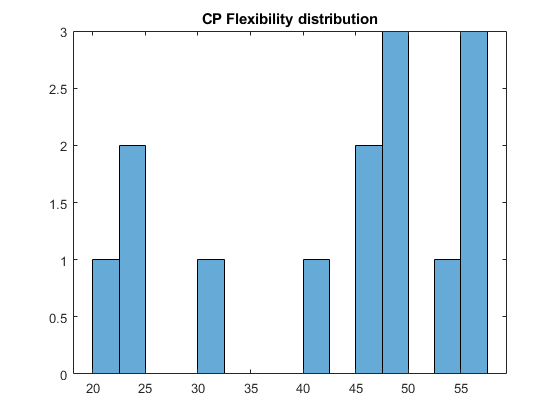

CP_Flexibility = Flex_results.Maximum_ROM(Flex_results.Group == "CP"); %Flexibility CP group
TD_Flexibility = Flex_results.Maximum_ROM(Flex_results.Group == "TD"); % Flexibility TD group
histogram(CP_Flexibility,15),title('CP Flexibility distribution'),

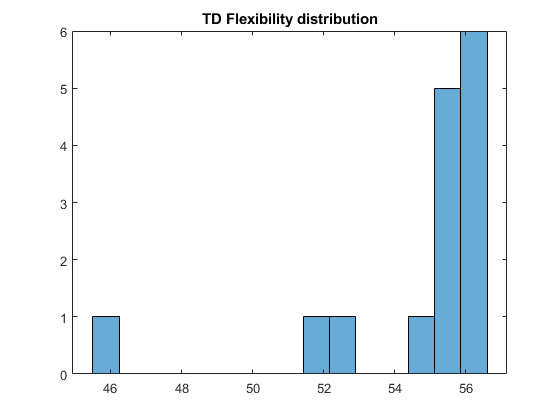

histogram(TD_Flexibility,15), title('TD Flexibility distribution'),

kurtosis_CP = kurtosis(CP_Flexibility)

kurtosis_CP =           1.98568547608479


kurtosis_TD = kurtosis(TD_Flexibility)

kurtosis_TD =           7.95701500551271


skewness_CP = skewness(CP_Flexibility)

skewness_CP =          -0.68361511370023


skewness_TD = skewness(TD_Flexibility)

skewness_TD =          -2.39486548525305


normalitytest(CP_Flexibility'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7924 	     0.5566                 1 
KS Stephens Modification       0.8384 	     0.0873                 1 
KS Marsaglia Method            0.7924 	     0.4915                 1 
KS Lilliefors Modification     0.2118 	     0.0889                 1 
Anderson-Darling Test          0.8468 	     0.0241                 0 
Cramer- Von Mises Test         0.1342 	     0.0386                 0 
Shapiro-Wilk Test              0.8544 	     0.0255                 0 
Shapiro-Francia Test           0.8750 	     0.0476                 0 
Jarque-Bera Test               1.6906 	     0.4294                 1 
DAgostino & Pearson Test       2.4235 	     0.2977                 1 


normalitytest(TD_Flexibility');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.3560 	     0.0506                 1 
KS Stephens Modification       1.4293 	     0.0100                 0 
KS Marsaglia Method            1.3560 	     0.0379                 0 
KS Lilliefors Modification     0.3501 	     0.0000                 0 
Anderson-Darling Test          2.4743 	     0.0000                 0 
Cramer- Von Mises Test         0.4576 	     0.0000                 0 
Shapiro-Wilk Test              0.6063 	     0.0000                 0 
Shapiro-Francia Test           0.5865 	     0.0001                 0 
Jarque-Bera Test               29.6960 	     0.0000                 0 
DAgostino & Pearson Test       25.0886 	     0.0000                 0 


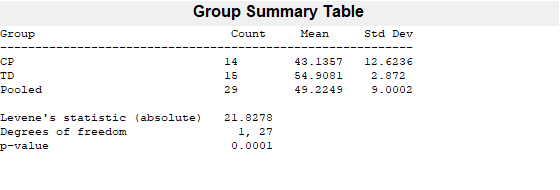

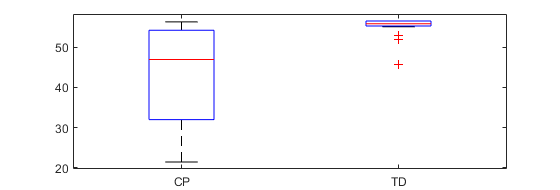

p =       7.35368124340931e-05


p = vartestn(Flex_results.Maximum_ROM,Flex_results.Group,'TestType','LeveneAbsolute')

p = vartestn(Flex_results.Maximum_ROM,Flex_results.Group,'TestType','LeveneQuadratic','display','off')

p =        0.00150322893443796


[p,h,stats] = ranksum(CP_Flexibility,TD_Flexibility,'method','exact') %Wilcoxon rank sum test

p =        0.00103689125509485


h = logical
   1


stats = struct with fields:
    ranksum: 138


median(CP_Flexibility)

ans =           46.9207763671875


iqr(CP_Flexibility)

ans =           22.2259521484375


median(TD_Flexibility)

ans =            55.816162109375


iqr(TD_Flexibility)

ans =           1.24002075195313


## Passive Ankle Joint Flexibility

*TD group does not have normal distribution and groups have unequal variances - Wilcoxon rank sum test was used. TD group has statistically higher passive range of motion compared to the CP group. 14 CP 14 TD (-5102, -5202 no emg).*

Passive_Flex_descriptives = groupsummary(Flex_results,"Group",{'mean','std','median','min','max','var'},'Passive_ROM')

Passive_Flex_descriptives = 2×8 table
    Group    GroupCount    mean_Passive_ROM    std_Passive_ROM     median_Passive_ROM    min_Passive_ROM    max_Passive_ROM     var_Passive_ROM 
    _____    __________    ________________    ________________    __________________    _______________    ________________    ________________

     CP          14        30.3157211216518    15.4507438079385     28.5751342773438       7.87353515625    55.8741455078125     238.72548421855
     TD          15        48.3041643415179    8.76739558717563     51.6215209960938     30.804443359375                56.5    76.8672253820267


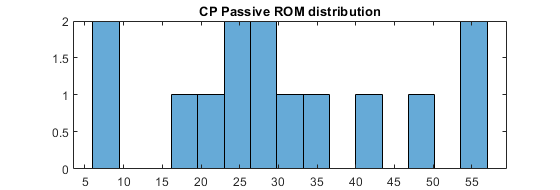

CP_Passive_Flex = Flex_results.Passive_ROM(Flex_results.Group == "CP"); %Flexibility CP group
TD_Passive_Flex = rmmissing(Flex_results.Passive_ROM(Flex_results.Group == "TD")); % Flexibility TD group
histogram(CP_Passive_Flex,15),title('CP Passive ROM distribution'),

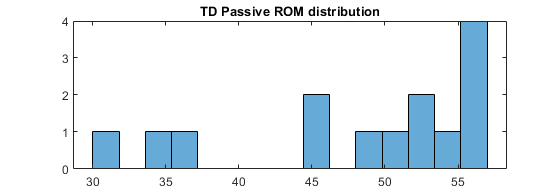

histogram(TD_Passive_Flex,15), title('TD Passive ROM distribution'), 

kurtosis_CP = kurtosis(CP_Passive_Flex)

kurtosis_CP =           2.09711239809428


kurtosis_TD = kurtosis(TD_Passive_Flex) 

kurtosis_TD =           2.43766344920069


skewness_CP = skewness(CP_Passive_Flex)

skewness_CP =          0.257890245743961


skewness_TD = skewness(TD_Passive_Flex) 

skewness_TD =          -0.90767177295598


normalitytest(CP_Passive_Flex'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5421 	     0.9305                 1 
KS Stephens Modification       0.5736 	     0.1500                 1 
KS Marsaglia Method            0.5421 	     0.8904                 1 
KS Lilliefors Modification     0.1449 	     0.2000                 1 
Anderson-Darling Test          0.2765 	     0.6561                 1 
Cramer- Von Mises Test         0.0386 	     0.7076                 1 
Shapiro-Wilk Test              0.9486 	     0.5393                 1 
Shapiro-Francia Test           0.9641 	     0.7003                 1 
Jarque-Bera Test               0.6307 	     0.7295                 1 
DAgostino & Pearson Test       0.6223 	     0.7326                 1 


normalitytest(TD_Passive_Flex');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7866 	     0.5661                 1 
KS Stephens Modification       0.8322 	     0.0913                 1 
KS Marsaglia Method            0.7866 	     0.5007                 1 
KS Lilliefors Modification     0.2102 	     0.0942                 1 
Anderson-Darling Test          0.9128 	     0.0180                 0 
Cramer- Von Mises Test         0.1459 	     0.0270                 0 
Shapiro-Wilk Test              0.8434 	     0.0181                 0 
Shapiro-Francia Test           0.8575 	     0.0288                 0 
Jarque-Bera Test               2.1068 	     0.3487                 1 
DAgostino & Pearson Test       2.9335 	     0.2307                 1 


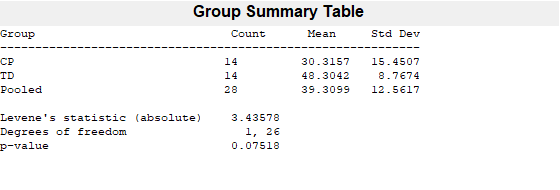

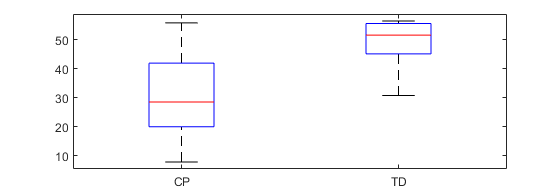

p =         0.0751787363091546


p = vartestn(Flex_results.Passive_ROM,Flex_results.Group,'TestType','LeveneAbsolute')

p = vartestn(Flex_results.Passive_ROM,Flex_results.Group,'TestType','LeveneQuadratic','display','off')

p =         0.0376998945145784


[p,h,stats] = ranksum(CP_Passive_Flex,TD_Passive_Flex) %Wilcoxon rank sum test

p =        0.00224356958169221


h = logical
   1


stats = struct with fields:
       zval: -3.05593891640961
    ranksum: 136


median(CP_Passive_Flex)

ans =           28.5751342773438


iqr(CP_Passive_Flex)

ans =             21.94873046875


median(TD_Passive_Flex)

ans =           51.6215209960938


iqr(TD_Passive_Flex)

ans =            10.486083984375


## Passive peak torque

*CP/TD data is not normal. Groups have equal variances. TD group has statistically higher passive peak torque compared to the CP group. 14 CP and 14 TD. *

Passive_PT_descriptives = groupsummary(Flex_results,"Group",{'mean','std','median','min','max','var'},'Passive_PT')

Passive_PT_descriptives = 2×8 table
    Group    GroupCount    mean_Passive_PT      std_Passive_PT     median_Passive_PT      min_Passive_PT       max_Passive_PT      var_Passive_PT 
    _____    __________    ________________    ________________    _________________    __________________    ________________    ________________

     CP          14        5.30289631049277    6.76097917052524    4.57510484498926     0.0496058352291584    26.1453755304683    45.7108393442762
     TD          15        5.83931849102149    3.63175411136542     4.9962377169868        2.1175490913447    15.0140327960253    13.1896379254196


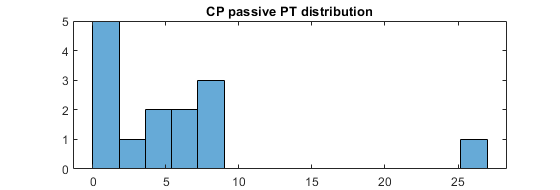

CP_Passive_PT = Flex_results.Passive_PT(Flex_results.Group == "CP"); % PT CP group
TD_Passive_PT = rmmissing(Flex_results.Passive_PT(Flex_results.Group == "TD")); % PT TD group
histogram(CP_Passive_PT,15),title('CP passive PT distribution'),

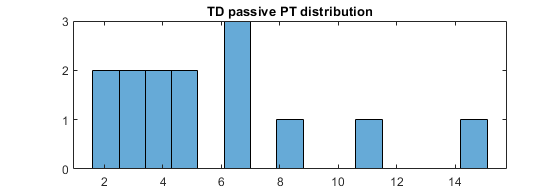

histogram(TD_Passive_PT,15), title('TD passive PT distribution'),

kurtosis_CP = kurtosis(CP_Passive_PT)

kurtosis_CP =           7.61997682317685


kurtosis_TD = kurtosis(TD_Passive_PT)

kurtosis_TD =           4.02132713044265


skewness_CP = skewness(CP_Passive_PT)

skewness_CP =           2.17339322120182


skewness_TD = skewness(TD_Passive_PT)

skewness_TD =           1.28695758494702


normalitytest(CP_Passive_PT'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.0419 	     0.2278                 1 
KS Stephens Modification       1.1024 	     0.0100                 0 
KS Marsaglia Method            1.0419 	     0.1882                 1 
KS Lilliefors Modification     0.2785 	     0.0043                 0 
Anderson-Darling Test          1.3979 	     0.0022                 0 
Cramer- Von Mises Test         0.2036 	     0.0048                 0 
Shapiro-Wilk Test              0.7060 	     0.0004                 0 
Shapiro-Francia Test           0.6852 	     0.0005                 0 
Jarque-Bera Test               23.4726 	     0.0000                 0 
DAgostino & Pearson Test       22.5608 	     0.0000                 0 


normalitytest(TD_Passive_PT');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7091 	     0.6960                 1 
KS Stephens Modification       0.7503 	     0.1500                 1 
KS Marsaglia Method            0.7091 	     0.6295                 1 
KS Lilliefors Modification     0.1895 	     0.1860                 1 
Anderson-Darling Test          0.6974 	     0.0464                 0 
Cramer- Von Mises Test         0.1028 	     0.1028                 1 
Shapiro-Wilk Test              0.8647 	     0.0353                 0 
Shapiro-Francia Test           0.8605 	     0.0313                 0 
Jarque-Bera Test               4.4731 	     0.1068                 1 
DAgostino & Pearson Test       8.0378 	     0.0180                 0 


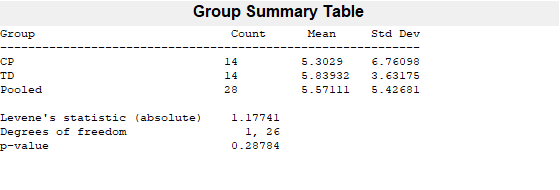

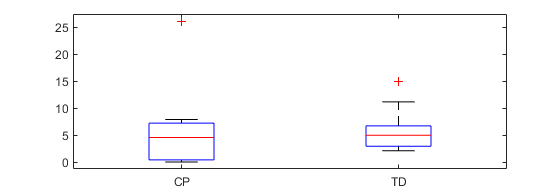

p =          0.287843514590129


p = vartestn(Flex_results.Passive_PT,Flex_results.Group,'TestType','LeveneAbsolute')

p = vartestn(Flex_results.Passive_PT,Flex_results.Group,'TestType','LeveneQuadratic','display','off')

p =          0.336810102559423


[p,h,stats] = ranksum(CP_Passive_PT,TD_Passive_PT) %Wilcoxon rank sum test

p =          0.346229789637118


h = logical
   0


stats = struct with fields:
       zval: -0.941927441321777
    ranksum: 182


median(CP_Passive_PT)

ans =           4.57510484498926


iqr(CP_Passive_PT)

ans =           6.80013324599713


median(rmmissing(TD_Passive_PT))

ans =            4.9962377169868


iqr(rmmissing(TD_Passive_PT))

ans =           3.77421971366629


## Passive energy 

### Explore each method of analysis should be used

Passive energy was calculated using 4 criteria:

- from 15PF to EMG onset;

- from 10PF to EMG onset;

- from 5PF to EMG onset;

- from min torque (i.e. point in which the inertial artefact was over) to EMG onset.

Here is the amount of participants that are excluded in each analysis (i.e. participants that do not have enough passive ROM):

sum(isnan(Flex_all.Passive_energy_5PF))

ans =     10


sum(isnan(Flex_all.Passive_energy_10PF))

ans =      7


sum(isnan(Flex_all.Passive_energy_15PF))

ans =      5


sum(isnan(Flex_all.Passive_energy_0torque))

ans =      4


The 0_torque calculation has the advantage of having a higher sample size, however it does not guarantee the same range of motion between participants. Thus, PF15 is the most adequate. 

## Passive energy* - from 15deg of plantarflexion to EMG onset*

*Both groups are not normally distributed and have equal variances. TD group has statistically higher passive energy than the CP group. 8 CP, 15 TD.*

PE_15_descriptives = groupsummary(Flex_results,"Group",{'mean','std','median','min','max','var'},'Passive_energy_15PF')

PE_15_descriptives = 2×8 table
    Group    GroupCount    mean_Passive_energy_15PF    std_Passive_energy_15PF    median_Passive_energy_15PF    min_Passive_energy_15PF    max_Passive_energy_15PF    var_Passive_energy_15PF
    _____    __________    ________________________    _______________________    __________________________    _______________________    _______________________    _______________________

     CP          14            8.03580080493254           10.9394250994523             5.00161555792583                            0          36.8937188452913           119.671021506527    
     TD          15            6.39904533602196           4.99548476461563             4.36053736700667            0.905316827

### Kurtosis, Skewness, Normality and Equal variances.

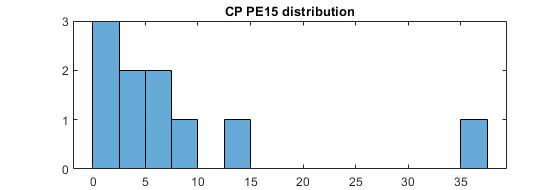

CP_PE_15 = rmmissing(Flex_results.Passive_energy_15PF(Flex_results.Group == "CP")); % PE15 CP group
TD_PE_15 = rmmissing(Flex_results.Passive_energy_15PF(Flex_results.Group == "TD")); % PE15 TD group
histogram(CP_PE_15,15),title('CP PE15 distribution'),

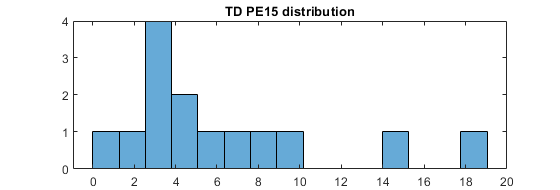

histogram(TD_PE_15,15), title('TD PE15 distribution'),

kurtosis_CP = kurtosis(CP_PE_15)

kurtosis_CP =           6.07970330767218


kurtosis_TD = kurtosis(TD_PE_15)

kurtosis_TD =           4.03560814974973


skewness_CP = skewness(CP_PE_15)

skewness_CP =           2.02045955059844


skewness_TD = skewness(TD_PE_15)

skewness_TD =           1.36230666313592


normalitytest(CP_PE_15'); %too small for SW test

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7609 	     0.6088                 1 
KS Stephens Modification       0.8232 	     0.0972                 1 
KS Marsaglia Method            0.7609 	     0.5322                 1 
KS Lilliefors Modification     0.2406 	     0.1049                 1 
Anderson-Darling Test          1.2254 	     0.0046                 0 
Cramer- Von Mises Test         0.1928 	     0.0066                 0 
Shapiro-Wilk Test              0.7098 	     0.0025                 0 
Shapiro-Francia Test           0.6885 	     0.0020                 0 
Jarque-Bera Test               10.7557 	     0.0046                 0 
DAgostino & Pearson Test       18.5815 	     0.0001                 0 


normalitytest(TD_PE_15');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7313 	     0.6587                 1 
KS Stephens Modification       0.7737 	     0.1500                 1 
KS Marsaglia Method            0.7313 	     0.5917                 1 
KS Lilliefors Modification     0.1954 	     0.1531                 1 
Anderson-Darling Test          0.9223 	     0.0173                 0 
Cramer- Von Mises Test         0.1510 	     0.0231                 0 
Shapiro-Wilk Test              0.8443 	     0.0186                 0 
Shapiro-Francia Test           0.8369 	     0.0163                 0 
Jarque-Bera Test               4.9560 	     0.0839                 1 
DAgostino & Pearson Test       8.6125 	     0.0135                 0 


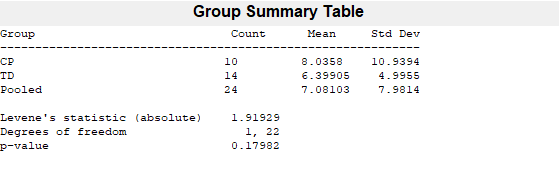

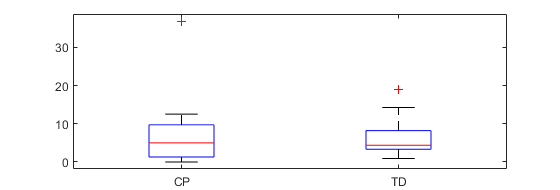

p =          0.179821796739067


p = vartestn(Flex_results.Passive_energy_15PF,Flex_results.Group,'TestType','LeveneAbsolute')

p = vartestn(Flex_results.Passive_energy_15PF,Flex_results.Group,'TestType','LeveneQuadratic','display','off')

p =          0.233893393347891


[p,h,stats] = ranksum(CP_PE_15,TD_PE_15) %Wilcoxon rank sum test

p =          0.837584952477175


h = logical
   0


stats = struct with fields:
       zval: -0.204983581812123
    ranksum: 121


median(CP_PE_15)

ans =           5.00161555792583


iqr(CP_PE_15)

ans =           8.44107877355418


median(rmmissing(TD_PE_15))

ans =           4.36053736700667


iqr(rmmissing(TD_PE_15))

ans =           4.88117956581002


## Passive energy* - from 0 torque to EMG onset*

## Quality check 

Since this method starts to calculate the integral as soon as torque hits its minimum value (i.e. end of the movement artefact, which is varible!), it is important to check what was the actuall range of motion in both groups. Results:  Groups do not have statistically significant difference between the range of motion in this analysis, however, differences in minimum and maximum values are very large between groups (see descriptives table), thus this analysis is not appropriate. 

Range_0torque_descriptives = groupsummary(Flex_results,"Group",{'mean','std','median','min','max','var'},'Range_0torque_EMG')

Range_0torque_descriptives = 2×8 table
    Group    GroupCount    mean_Range_0torque_EMG    std_Range_0torque_EMG    median_Range_0torque_EMG    min_Range_0torque_EMG    max_Range_0torque_EMG    var_Range_0torque_EMG
    _____    __________    ______________________    _____________________    ________________________    _____________________    _____________________    _____________________

     CP          14           18.3484411969866         12.8614990654165            21.282958984375                       0              34.7412109375          165.41815820971   
     TD          15           28.3274793526786         14.5460102420749           24.9433564453125             12.01171875           67.8009033203125     

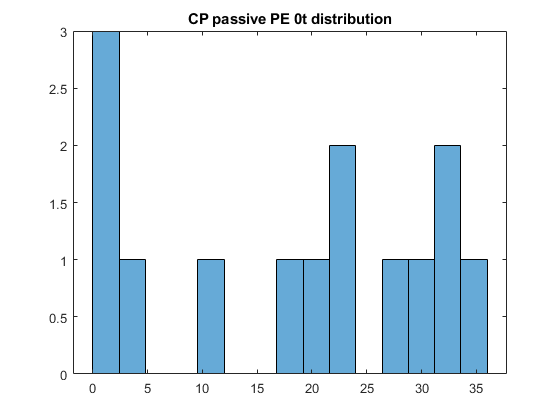

CP_PE_0t_range = Flex_results.Range_0torque_EMG(Flex_results.Group == "CP"); % PE 0torque CP group
TD_PE_0t_range = rmmissing(Flex_results.Range_0torque_EMG(Flex_results.Group == "TD")); % PE 0torque TD group
figure, histogram(CP_PE_0t_range,15),title('CP passive PE 0t distribution'),

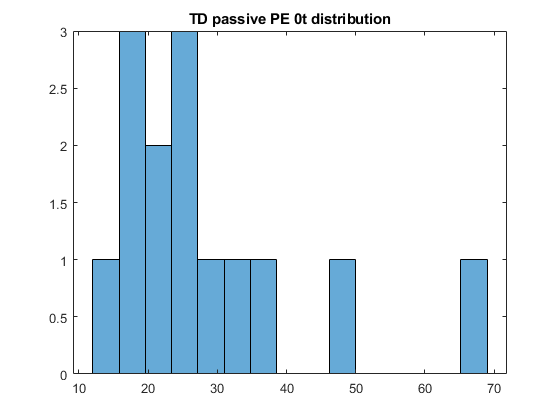

figure, histogram(TD_PE_0t_range,15), title('TD passive PE 0t distribution'),

kurtosis_TD = kurtosis(TD_PE_0t_range)

kurtosis_TD =           5.00418246058124


kurtosis_CP = kurtosis(CP_PE_0t_range)

kurtosis_CP =            1.6059410429957


skewness_TD = skewness(TD_PE_0t_range)

skewness_TD =           1.57931233350983


skewness_CP = skewness(CP_PE_0t_range)

skewness_CP =         -0.321734254682212


normalitytest(CP_PE_0t_range'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5823 	     0.8868                 1 
KS Stephens Modification       0.6161 	     0.1500                 1 
KS Marsaglia Method            0.5823 	     0.8370                 1 
KS Lilliefors Modification     0.1556 	     0.2000                 1 
Anderson-Darling Test          0.6167 	     0.0661                 1 
Cramer- Von Mises Test         0.0859 	     0.1740                 1 
Shapiro-Wilk Test              0.8861 	     0.0711                 1 
Shapiro-Francia Test           0.9113 	     0.1435                 1 
Jarque-Bera Test               1.3752 	     0.5028                 1 
DAgostino & Pearson Test       3.6557 	     0.1608                 1 


normalitytest(TD_PE_0t_range');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7936 	     0.5546                 1 
KS Stephens Modification       0.8396 	     0.0864                 1 
KS Marsaglia Method            0.7936 	     0.4896                 1 
KS Lilliefors Modification     0.2121 	     0.0879                 1 
Anderson-Darling Test          0.9212 	     0.0174                 0 
Cramer- Von Mises Test         0.1510 	     0.0231                 0 
Shapiro-Wilk Test              0.8343 	     0.0137                 0 
Shapiro-Francia Test           0.8196 	     0.0103                 0 
Jarque-Bera Test               8.1630 	     0.0169                 0 
DAgostino & Pearson Test       12.4786 	     0.0020                 0 


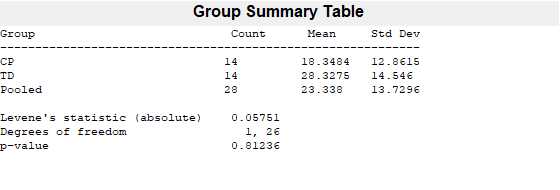

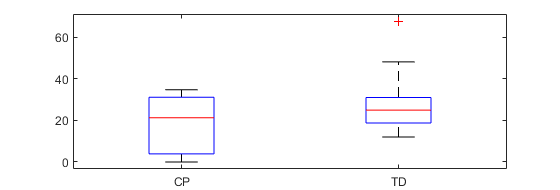

p =          0.812359329423092


p = vartestn(Flex_results.Range_0torque_EMG,Flex_results.Group,'TestType','LeveneAbsolute')

p = vartestn(Flex_results.Range_0torque_EMG,Flex_results.Group,'TestType','LeveneQuadratic','display','off')

p =           0.70985728412471


[p,h,stats] = ranksum(CP_PE_0t_range,TD_PE_0t_range) %Wilcoxon rank sum test

p =           0.24126684106089


h = logical
   0


stats = struct with fields:
       zval: -1.17182620102925
    ranksum: 177


## Stretch velocity

A very low stretch velocity for this test was used to prevent stretch reflexes. However the heavy dynamometer was moved manually by the examiner. Thus, it is important to check the variability and differences between groups. 14 CP and 14 TD.

Both groups have normally distributed data and have equal variances. 

Velocity_descriptives = groupsummary(Flex_results,"Group",{'mean','std','median','min','max','var'},'Stretch_vel')

Velocity_descriptives = 2×8 table
    Group    GroupCount    mean_Stretch_vel     std_Stretch_vel     median_Stretch_vel    min_Stretch_vel     max_Stretch_vel      var_Stretch_vel 
    _____    __________    ________________    _________________    __________________    ________________    ________________    _________________

     CP          14        7.23002655619722    0.953153382026543     7.12159139677188     5.86547596292085    8.84766290103863    0.908501369668638
     TD          15        9.56530021219193     2.46165556326256     9.43511120095637     5.55547004907099    16.1063787234201     6.05974811214149


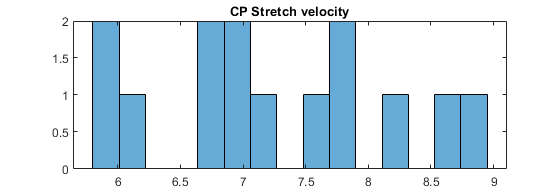

CP_vel = Flex_results.Stretch_vel(Flex_results.Group == "CP"); % Stretch vel CP group
TD_vel = rmmissing(Flex_results.Stretch_vel(Flex_results.Group == "TD")); % Stretch vel TD group
histogram(CP_vel,15),title('CP Stretch velocity'),

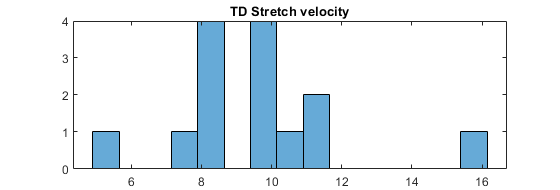

histogram(TD_vel,15), title('TD Stretch velocity'),

kurtosis_CP = kurtosis(CP_vel)

kurtosis_CP =           2.02217487439634


kurtosis_TD = kurtosis(TD_vel)

kurtosis_TD =           4.85333875662252


skewness_CP = skewness(CP_vel)

skewness_CP =           0.16504683368425


skewness_TD = skewness(TD_vel)

skewness_TD =           1.11387858146995


normalitytest(CP_vel'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.3852 	     0.9984                 1 
KS Stephens Modification       0.4075 	     0.1500                 1 
KS Marsaglia Method            0.3852 	     0.9947                 1 
KS Lilliefors Modification     0.1029 	     0.2000                 1 
Anderson-Darling Test          0.2068 	     0.8689                 1 
Cramer- Von Mises Test         0.0235 	     0.9299                 1 
Shapiro-Wilk Test              0.9582 	     0.6934                 1 
Shapiro-Francia Test           0.9740 	     0.8630                 1 
Jarque-Bera Test               0.6213 	     0.7330                 1 
DAgostino & Pearson Test       0.6739 	     0.7139                 1 


normalitytest(TD_vel');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5034 	     0.9617                 1 
KS Stephens Modification       0.5326 	     0.1500                 1 
KS Marsaglia Method            0.5034 	     0.9324                 1 
KS Lilliefors Modification     0.1345 	     0.2000                 1 
Anderson-Darling Test          0.5196 	     0.1867                 1 
Cramer- Von Mises Test         0.0711 	     0.2709                 1 
Shapiro-Wilk Test              0.9091 	     0.1529                 1 
Shapiro-Francia Test           0.8848 	     0.0635                 1 
Jarque-Bera Test               4.8987 	     0.0863                 1 
DAgostino & Pearson Test       8.7793 	     0.0124                 0 


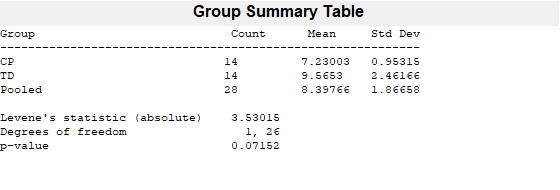

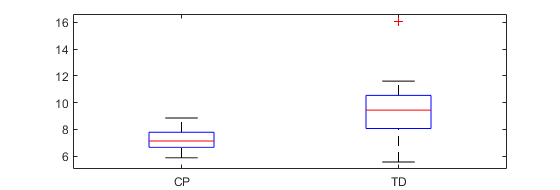

p =         0.0715178813600245


p = vartestn(Flex_results.Stretch_vel,Flex_results.Group,'TestType','LeveneAbsolute')

p = vartestn(Flex_results.Stretch_vel,Flex_results.Group,'TestType','LeveneQuadratic','display','off')

p =          0.131618980670257


[h,p,ci,stats] = ttest2(CP_vel,TD_vel)% independent t-test 

h =      1


p =        0.00273855930055011


ci =          -3.78545237852747
        -0.885094933461966


stats = struct with fields:
    tstat: -3.31009114435266
       df: 26
       sd: 1.86658102982567


stats_Vel = mes(TD_vel,CP_vel,'hedgesg','exactCi',true) %hedge´s g

stats_Vel = struct with fields:
            isDep: 0
            nBoot: 0
        confLevel: 0.95
                n: [2×1 double]
                t: [1×1 struct]
          hedgesg: 1.21465714076482
        hedgesgCi: [2×1 double]
    hedgesgCiType: 'exact analytical'
